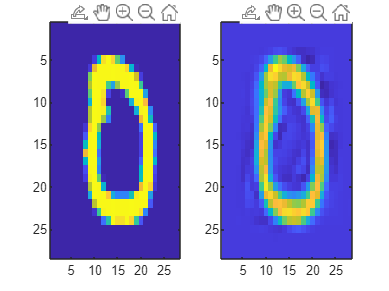

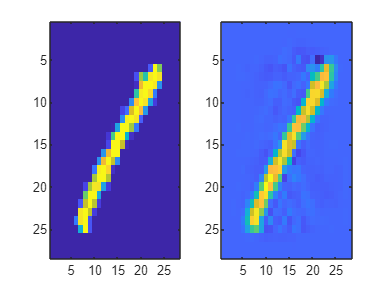

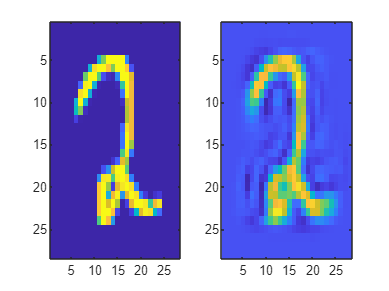

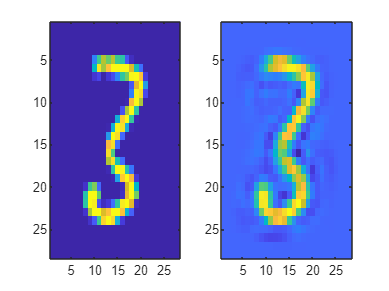

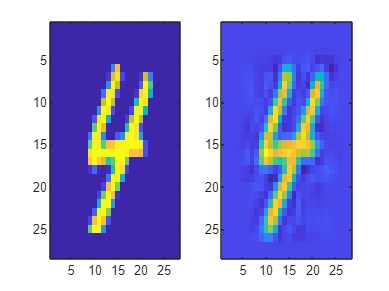

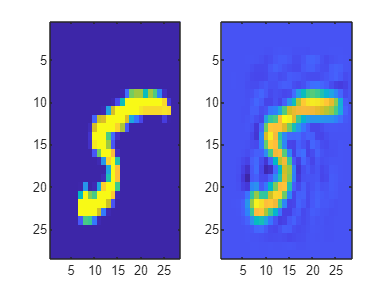

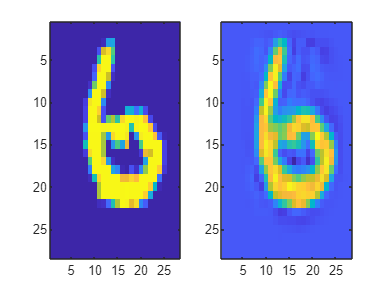

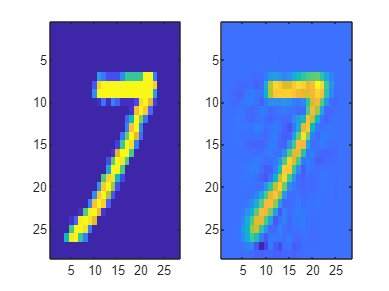

% Loading the data
load mnist digits_train labels_train

% Extracting size of data 
size_data = size(digits_train);
NUM = size_data(3);

% The final dimensions
DIM_END = 84;

% The sample number to be displayed
SAMPLE_NUM = 2003;

% To store the number of elements of each digit
count = zeros(10,1);

% The expected max size of data pf each digit, in worst case can be set =
% NUM, here it is set to twice of NUM/10
MAX_SIZE_OF_SINGLE_DIGIT = NUM/10 *2;

% To store the data
data = zeros(784,MAX_SIZE_OF_SINGLE_DIGIT,10);

% Filling the created arrays
for i=1:NUM
    count(labels_train(i)+1) = count(labels_train(i)+1) +1;
    data(:,count(labels_train(i)+1),labels_train(i)+1)= reshape(digits_train(:,:,i),[784,1]);
end

% Loop to compress data and then extract the SAMPLE_NUM image for each
% digit
for u=1:10
    % Removing extra redundant columns for this digit
    x = data(:,1:count(u),u);

    % Getting the compressed data along with the last DIM_END eigen vectors
    [values, vec] = compress(x,DIM_END);

    % To extract the image from the compressed data
    calculate = zeros(784,1);
    for t=1:DIM_END
        calculate(:) = calculate(:)+(values(t,SAMPLE_NUM))*vec(:,t);
    end
       
    % Plotting the original data alongside the extracted data of lower
    % dimension
    figure(u);
    subplot(1,2,1), imagesc(reshape(data(:,SAMPLE_NUM,u),[28,28]));
    subplot(1,2,2), imagesc(reshape(calculate,[28,28]));
end